close all; clearvars; clc;

## Setting everything up

T = 10;
dT = 0.01;
trans = 2;

t = 0:dT:T-dT+trans;

F = 1/dT;
dF = 1/T;

f = 0:dF:F-dF;

N = T/(2*dT) - 20;
f_d = f(f<N*dF);

freqs = 1:length(f);
freqs(N:end) = 0;
signal = 0.05*sin(freqs(1)*2*pi*dF*t + rand*2*pi);

for i = 2:length(freqs)
    signal = signal + 0.05*sin(freqs(i)*2*pi*dF*t + rand*2*pi);
end
signal = signal - mean(signal);

## MATLAB Designed Filter

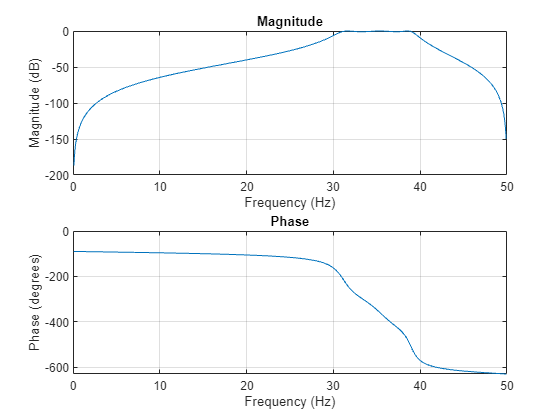

[b,a] = cheby1(3, 1,[31 39]/(F/2));
figure
freqz(b, a, [], F)

## Testing the Filter and Real-Time Implementation

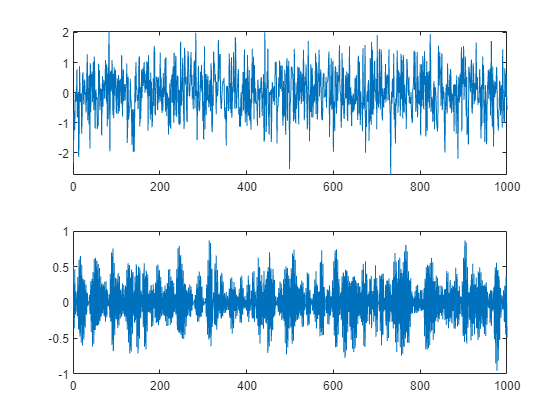

% Author of this filter implementation: Jan Simon, Heidelberg, (C) 2011
n = length(a);
b = b / a(1);  % [Edited, Jan, 26-Oct-2014, normalize parameters]
a = a / a(1);
X = signal;
Y = zeros(size(X));
z = zeros(size(a));

for m = 1:length(X)
   Y(m) = b(1) * X(m) + z(1);
   for i = 2:n
      z(i-1) = b(i)*X(m) + z(i) - a(i)*Y(m);
   end
end
Y = Y(t>=trans);
X = X(t>=trans);

figure
subplot(2,1,1)
plot(X)
subplot(2,1,2)
plot(Y)

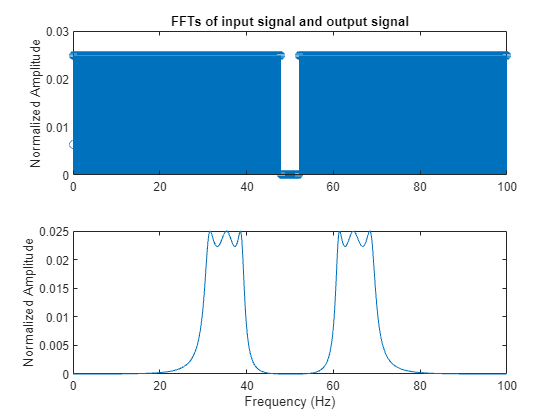

y_fft = fft(Y/length(Y));
x_fft = fft(X/length(X));

figure
subplot(2,1,1)
stem(f, abs(x_fft))
title("FFTs of input signal and output signal")
ylabel("Normalized Amplitude")
subplot(2,1,2)
plot(f, abs(y_fft))
xlabel("Frequency (Hz)")
ylabel("Normalized Amplitude")